Author: **Arjan Gupta**

Due: March 27, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Forward Dyanamics of Three Link Manipuator

clear; clc; close all;

## Build Robot

### Create Rigid Body Elements

First, let us create a `rigidBodyTree` robot model. Then, we create the 3 rectangular arms of the robot.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");

Next, we create collision objects using the given link lengths in the prompt of this assignment. We use `Pose` in order to shift the frame origin down along the x-axis. The default origin is in the center of the object. 

% Link lengths
L1 = 4.0;
L2 = 3.0;
L3 = 2.0;
% Create collision objects for each body
coll1 = collisionBox(L1,0.2,0.2); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([-L1/2 0 0]);
coll2 = collisionBox(L2,0.2,0.2); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([-L2/1.3 0 0]);
coll3 = collisionBox(L3,0.2,0.2); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([-L3*1.3 0 0]);
% Add the collision bodies to the rigid body objects.
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)

### Attach Joints

We specify the joints as revolute and set them to rotate around the z-axis.

jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt1.JointAxis = [0 0 1];
jnt2.JointAxis = [0 0 1];
jnt3.JointAxis = [0 0 1];

In the prompt of this assignment, we are given the following DH table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 0 			& 0	& 0	& \theta_1			\cr
2			& L_1 		& 0		& 0	& \theta_2		\cr
3			& L_2 			& 0			& 0 & \theta_3	\cr
}$$


% Joint variables
theta1 = 0;
theta2 = 0;
theta3 = 0;
% DH table
dhparams = [0 0  0 theta1;
            L1 0 0 theta2;
            L2 0 0 theta3];
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

### Set Physical Properties

% Masses (in kgs), given in assignment prompt
m1 = 20;
m2 = 15;
m3 = 10;
% Moments of inertia (in kgm^2), given in assignment prompt
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;
% Set the masses
arm1.Mass = m1;
arm2.Mass = m2;
arm3.Mass = m3;
% Set the centers of masses
arm1.CenterOfMass = [L1/2, 0.1, 0.1];
arm2.CenterOfMass = [L2/2, 0.1, 0.1];
arm3.CenterOfMass = [L3/2, 0.1, 0.1];
% Set the inertias
arm1.Inertia = [I1,I1,I1,0,0,0];
arm2.Inertia = [I2,I2,I2,0,0,0];
arm3.Inertia = [I3,I3,I3,0,0,0];

### Assemble Robot

To assemble the robot, we add each joint to the body, and then add the body to the tree.

bodies = {base,arm1,arm2,arm3};
joints = {[],jnt1,jnt2,jnt3};
for i = 2:length(bodies)
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
end
disp("Home position:");

Home position:


show(robot,homeConfiguration(robot),"Collisions","on","Frames","off");

### Move robot

Now let's try to move the robot.

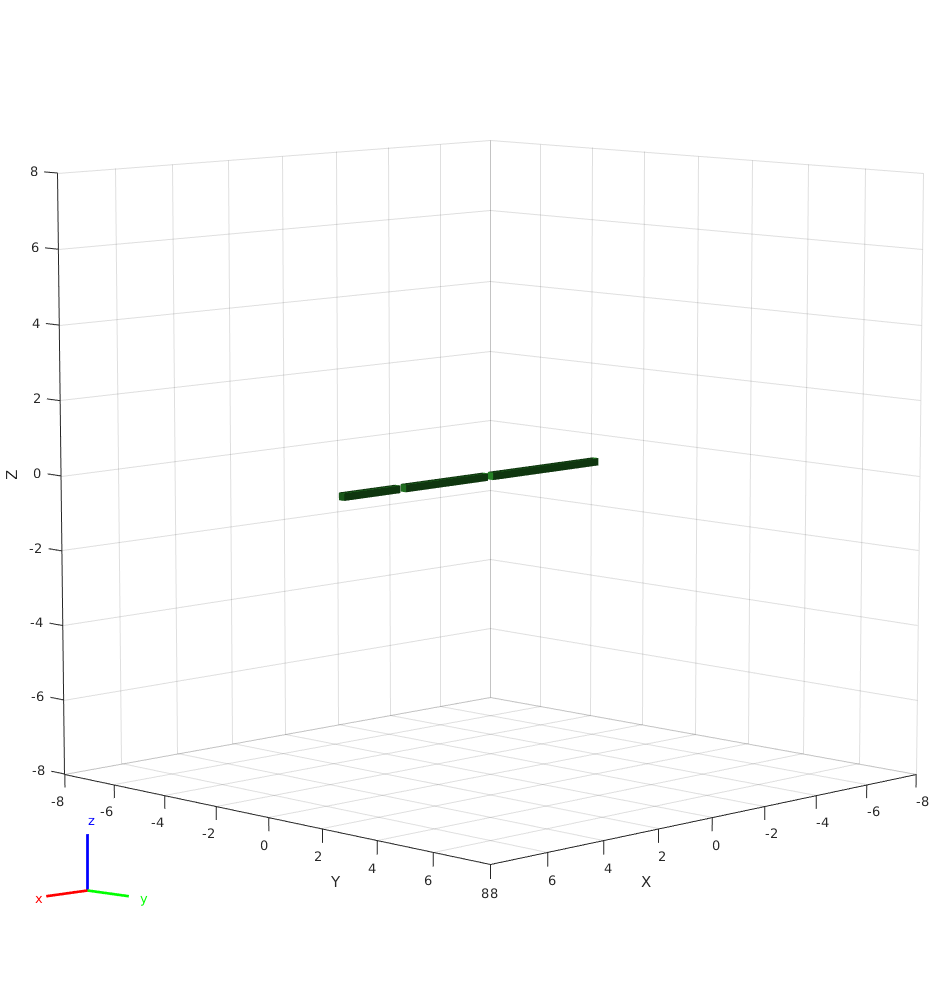

pause(1);

disp("Initial position for Problem 1:");

Initial position for Problem 1:


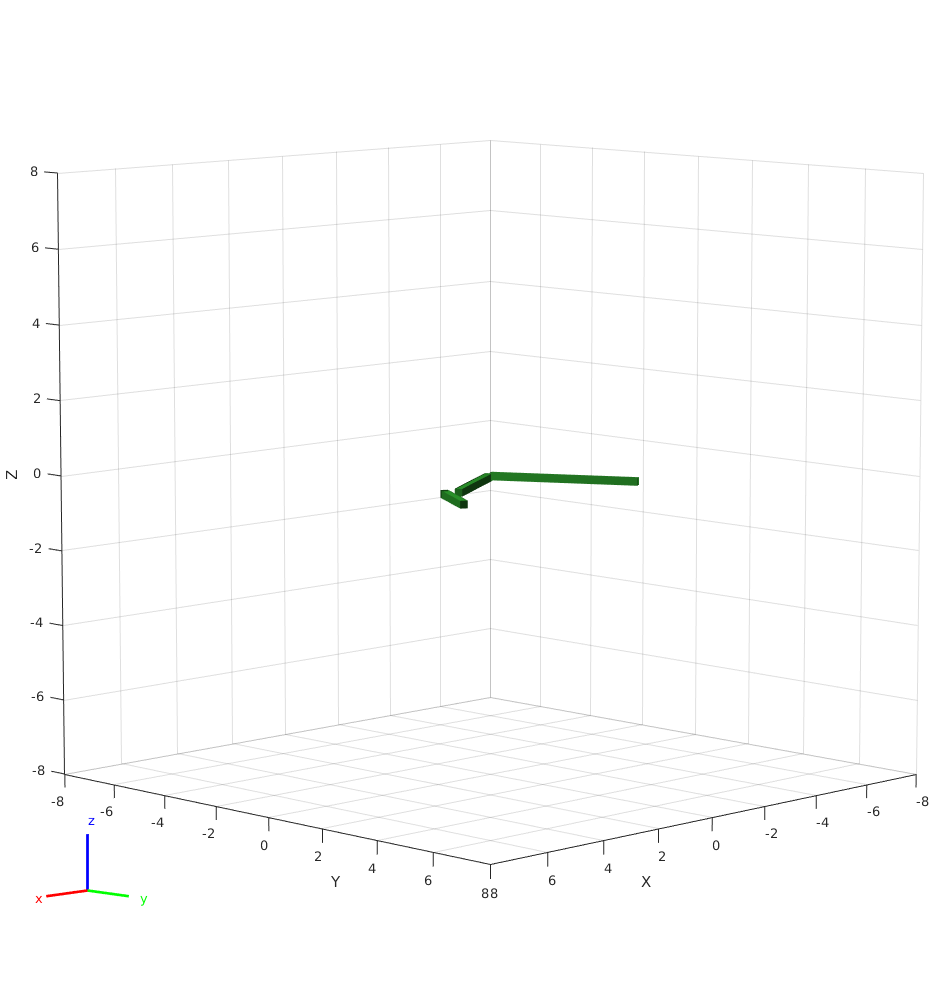

initialPosition = [-pi/3;pi/2;pi/6];
show(robot,initialPosition,"Collisions","on","Frames","off");

## Problem 1

In this problem we implement the forward dynamics and plot the joint accelerations and velocities in response to actuator torques.

% Set gravity direction
robot.Gravity = [0; -9.81; 0];
% Set joint torques and velocities, as given in assignment prompt
jointTorques = [20;5;1];
jointVelocities = [0;0;0];
% Calculate fwd dynamics for initial position
fDynHome = forwardDynamics(robot,initialPosition,jointVelocities,jointTorques);
display(fDynHome);

fDynHome =  -396.3828
  394.4978
    2.3563
